addpath(genpath('/datascience/projects/statisticallyfit/github/MATLAB/MatlabTutorial/AMTH250_NumericalMatlab/Numerical Analysis/Interpolation'))
addpath(genpath('/datascience/projects/statisticallyfit/github/MATLAB/MatlabTutorial/AMTH250_NumericalMatlab/Numerical Analysis/Least Squares'))

xData = [-1 -0.96 -0.86 -0.79 0.22 0.50 0.93];
yData = [-1 -0.151 0.894 0.986 0.895 0.5 -0.306];
n = length(xData);

% setting the range for the plot
xx = -1.2 : 0.01 : 1.2;
xInterp = -0.5; % value to find with interpolation

Find the INTERPOLATION (lagrange)

polyInterp = vpa(interpLagrange(xData, yData),17)

$$polyInterp = 0.043649939020604669\,x^{6}+16.076695441034388\,x^{5}-0.048402059220439907\,x^{4}-20.100476671429553\,x^{3}+0.016880653326955111\,x^{2}+5.0294636999939973\,x-0.0064460635282873819$$

Find interpolation polynomial coefficients with polyfit (gives the coefficients)

cc_interp = polyfit(xData, yData, n-1)

cc_interp =    0.043649939021261  16.076695441035099  -0.048402059221261 -20.100476671430421   0.016880653327234   5.029463699994216  -0.006446063528338


yy_interp = polyval(cc_interp, xx)

yy_interp =  -11.257861964817609 -10.432892170038649  -9.647572382146535  -8.900676001992421  -8.190998987837979  -7.517359666127947  -6.878598542231061  -6.273578111149636  -5.701182668197792  -5.160318119648114  -4.649911793346963  -4.168912249298398  -3.716289090216565  -3.291032772046680  -2.892154414454763  -2.518685611285621  -2.169678240989703  -1.844204277018347  -1.541355598187669  -1.260243799011017  -0.999999999999997  -0.759774657934038  -0.538737376098591  -0.336076714491832  -0.150999999999996   0.017266863458746   0.169479584821855   0.306375675801375   0.428674640834346   0.537078167064641   0.632270314356220   0.714917705337808   0.785669715479031   0.845158663197943   0.894000000000003   0.932792500648471   0.962118453366238   0.982543850069084   0.994618576630352   0.998876603177068   0.995836174417474   0.985999999999999   0.969855444903652   0.947874719859841   0.920515071805632   0.888218974368418   0.851414318382037   0.810514602434298   0.765919123445941   0.718

% compare that both interpolation yys are the same:
y_interp = polyval(cc_interp, xInterp)

y_interp =   -0.509137997201303


y_mine_interp = calcPoly(polyInterp, xInterp)

$$y\_mine\_interp = -0.50913799720125830045921290835451$$

y_interp - y_mine_interp % is the error

$$ans = -0.000000000000044960193381054377265680245456856$$

Find the cubic spline with not-a-knot conditions, from matlab's spline function

yy_spline = spline(xData, yData, -1:0.01:0.93);

Find the cubic spline with my function

polySpline = vpa(notAKnotCubicSpline(xData, yData));
vpa(polySpline, 6)

$$ans = \left(\begin{array}{c} 24.7783\,x-92.224\,{\left(x+1.0\right)}^{2}+84.7761\,{\left(x+1.0\right)}^{3}+23.7783\\ 17.8073\,x-82.0509\,{\left(x+0.96\right)}^{2}+84.7761\,{\left(x+0.96\right)}^{3}+16.944\\ 3.94044\,x-56.618\,{\left(x+0.86\right)}^{2}+272.88\,{\left(x+0.86\right)}^{3}+4.28278\\ 0.025246\,x+0.686735\,{\left(x+0.79\right)}^{2}-0.793008\,{\left(x+0.79\right)}^{3}+1.00594\\ 1.07371\,{\left(x-0.22\right)}^{3}-1.71608\,{\left(x-0.22\right)}^{2}-1.01439\,x+1.11817\\ 1.07371\,{\left(x-0.5\right)}^{3}-0.814161\,{\left(x-0.5\right)}^{2}-1.72286\,x+1.36143 \end{array}\right)$$

% evaluate my spline and compare with matlab: 
yy_spline_mine = calcSpline(xData, polySpline, -1:0.01:0.93);

[yy_spline_mine; yy_spline]' % yes they are almost equal

% now actually prepare to plot
yy_spline = spline(xData, yData, xx);

% compare the interpolation value - equal
y_spline = spline(xData, yData, xInterp)

y_spline =    1.031735079716040


y_spline_mine = calcSpline(xData, polySpline, xInterp)

$$y\_spline\_mine = 1.0317350797160403611237911122122$$

Evaluate the quadratic fit

cc_quadratic = polyfit(xData, yData, 2);
yy_quadratic = polyval(cc_quadratic, xx)

yy_quadratic =   -0.884677638151166  -0.845340255648798  -0.806357835767370  -0.767730378506881  -0.729457883867331  -0.691540351848721  -0.653977782451051  -0.616770175674320  -0.579917531518528  -0.543419849983676  -0.507277131069763  -0.471489374776790  -0.436056581104757  -0.400978750053662  -0.366255881623508  -0.331887975814293  -0.297875032626017  -0.264217052058681  -0.230914034112284  -0.197965978786826  -0.165372886082308  -0.133134755998729  -0.101251588536090  -0.069723383694391  -0.038550141473630  -0.007731861873810   0.022731455105071   0.052839809463013   0.082593201200016   0.111991630316078   0.141035096811202   0.169723600685386   0.198057141938630   0.226035720570935   0.253659336582301   0.280927989972727   0.307841680742214   0.334400408890761   0.360604174418368   0.386452977325036   0.411946817610765   0.437085695275555   0.461869610319404   0.486298562742315   0.510372552544286   0.534091579725317   0.557455644285409   0.580464746224562   0.603118885542775   0.

% interpolation value
y_quadratic = polyval(cc_quadratic, xInterp)

y_quadratic =    1.011704407445778


Now plot all the curves

figure(1); clf; hold on; grid on; grid minor

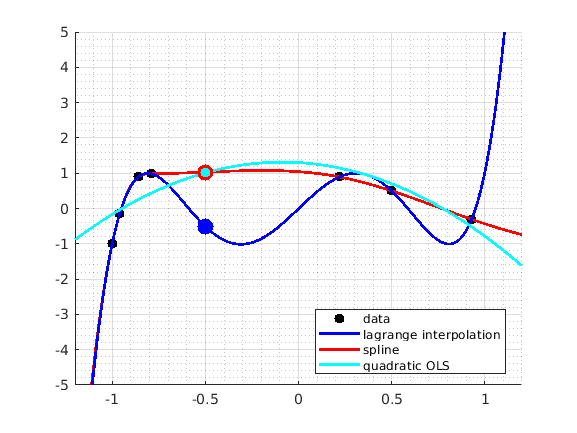

% plot data
h0 = plot(xData, yData, 'k.', 'MarkerSize', 25);
%plot approximations
h2 = plot(xx, yy_spline, 'r-', 'LineWidth', 2);
h1 = plot(xx, yy_interp, 'b-', 'LineWidth', 2);
h3 = plot(xx, yy_quadratic, 'c-', 'LineWidth', 2);
% plot the single interpolation values at xinterp = -0.5
plot(xInterp, y_interp, 'b.', 'MarkerSize', 40);
plot(xInterp, y_spline, 'r.', 'MarkerSize', 40);
plot(xInterp, y_quadratic, 'c.', 'MarkerSize', 25);

legend([h0 h1 h2 h3], {'data', 'lagrange interpolation','spline', 'quadratic OLS'}, 'Location', 'Best')
axis([-1.2, 1.2, -5 5])

% estimates
y_interp

y_interp =   -0.509137997201303


y_spline

y_spline =    1.031735079716040


y_quadratic

y_quadratic =    1.011704407445778
